# Predictive distributions

A predictive distribution is a probability distribution of the data. It can be used to estimate the uncertainty in predicted values of a model.

The variance in a predictive distribution of the data has two sources of variance: noise in the data and uncertainty in the parameters of a model of the data. One can think of the predictive distribution as the distribution of future, yet unseen data. For a regression problem, a predictive distribution is a distribution of $y$ for an implicit value of $x$.

### Prior predictive distribution

A prior predictive distribution is computed using the distribution of the noise and a prior distribution of the model parameters. It does not use data. Let $w$ be a model parameter. Then the prior predictive distribution for an unobserved value of $y$ is


$$p(\hat{y}) = \int p(\hat{y},w) d w = \int p(\hat{y}|w) p(w) d w$$


where the likelihood and the prior appear in the second integral above.

### Posterior predictive distribution

The posterior predictive distribution is computed using the distribution of the noise and a posterior distribution of the model parameters. The posterior distribution requires the use of data, $\mathbf{y}$. Again, let $w$ be a model parameter. Then the posterior predictive distribution for an unobserved value of $y$ is


$$p(\hat{y}|\mathbf{y}) = \int p(\hat{y},w|\mathbf{y}) d w = \int p(\hat{y}|w) p(w|\mathbf{y}) d w$$


where the likelihood and the posterior appear in the second integral above.

### Example: prior predictive distribution

Consider simple linear regression with Gaussian noise $N(0, 0.1)$. Let $p(w) = N([2 \; 1]^T, I/2)$ be a prior distribution of the regression parameters.

sigma2 = 0.1;    % noise variance
m0 = [2 1]';     % prior distribution mean
S0 = 0.5*eye(2); % prior distribution variance

Generate many samples of the prior predictive distribution for values of $x$ between -1 and 3.

ns = 10000;
x = rand(ns,1)*4-1;
w = randn(ns,2)*sqrt(0.5)+m0';
y = w(:,1) + w(:,2).*x;
clf; plot(x, y, 'k.'); ylim([-2 10]); hold on

Plot the linear regression model based using parameters that are the mean of the prior distribution.

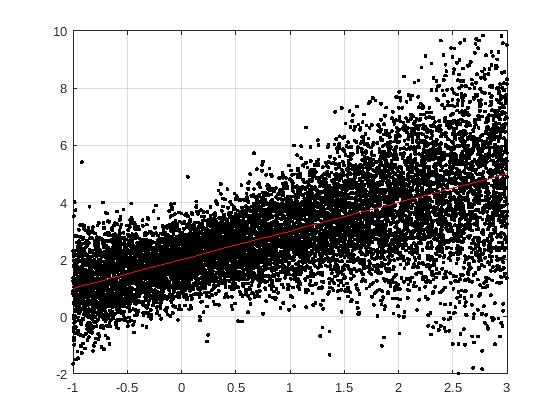

fplot(@(x) 2+x, [-1 3], 'r-');
grid on

Calculate the standard deviation of the prior predictive distribution.

phi = @(x) [1 x]';
xx = (-1:0.1:3)';
yy = zeros(size(xx));
ss = zeros(size(xx));
for i = 1:length(xx)
    yy(i) = m0'*phi(xx(i));
    ss(i) = sqrt(sigma2 + phi(xx(i))'*S0*phi(xx(i)));
end

Now plot the 2 standard deviation error bars.

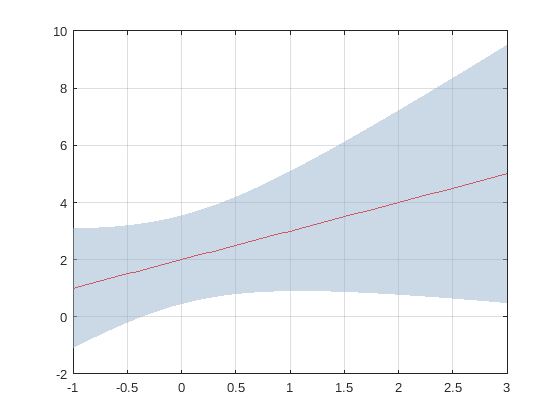

hi = yy+2*ss;
lo = yy-2*ss;
figure
plot(xx, yy, 'r-');
h = patch([xx; xx(end:-1:1); xx(1)], [lo; hi(end:-1:1); lo(1)], 'k');
set(h, 'EdgeAlpha',0, 'FaceColor',[.6 .7 .8], 'FaceAlpha',.5);
grid on

### Example: posterior predictive distribution

We continue the above example by using data to train the model and calculating the posterior predictive distribution.

Generate and plot synthetic training data for the ground truth $y=2+x$.

x = (1:0.2:2)';
n = length(x);
y = 2 + x + randn(n,1)*sqrt(sigma2);
figure; clf
plot(x, y, 'ko', 'MarkerFaceColor','k');
hold on

Calculate the posterior mean `mn` and covariance matrix `Sn`.

Phi = [ones(n,1) x];
beta = 1/sigma2;
Sn = inv(inv(S0) + beta*(Phi'*Phi));
mn = Sn*(beta*Phi'*y);

Calculate the standard deviation of the posterior predictive distribution.

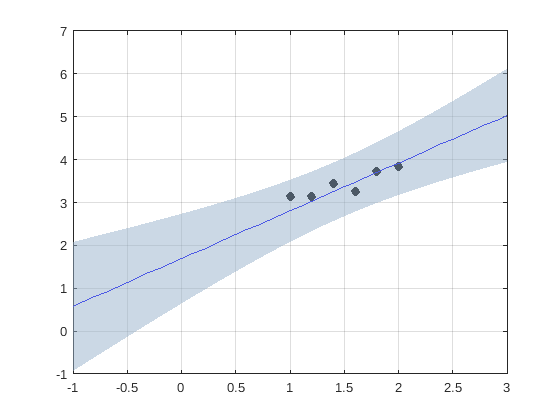

xx = (-1:0.1:3)';
yy = zeros(size(xx));
ss = zeros(size(xx));
for i = 1:length(xx)
  yy(i) = mn'*phi(xx(i));
  ss(i) = sqrt(sigma2 + phi(xx(i))'*Sn*phi(xx(i)));
end
plot(xx, yy, 'b-');
hold on
grid on
hi = yy+2*ss;
lo = yy-2*ss;
h = patch([xx; xx(end:-1:1); xx(1)], [lo; hi(end:-1:1); lo(1)], 'k');
set(h, 'EdgeAlpha',0, 'FaceColor',[.6 .7 .8], 'FaceAlpha',.5);

Notice that the variance is smaller where the data is located.

### Taking it further

- Experiment with different values of the noise and prior variance, and also different locations of the training data.

- What happens to the posterior predictive distribution when you use more data? Does the variance decrease?

- Extend the above examples to use degree 2 polynomial regression.